Distanze Lp

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [50528×3 double]
     Vertices: [25290×3 double]

  Show all properties


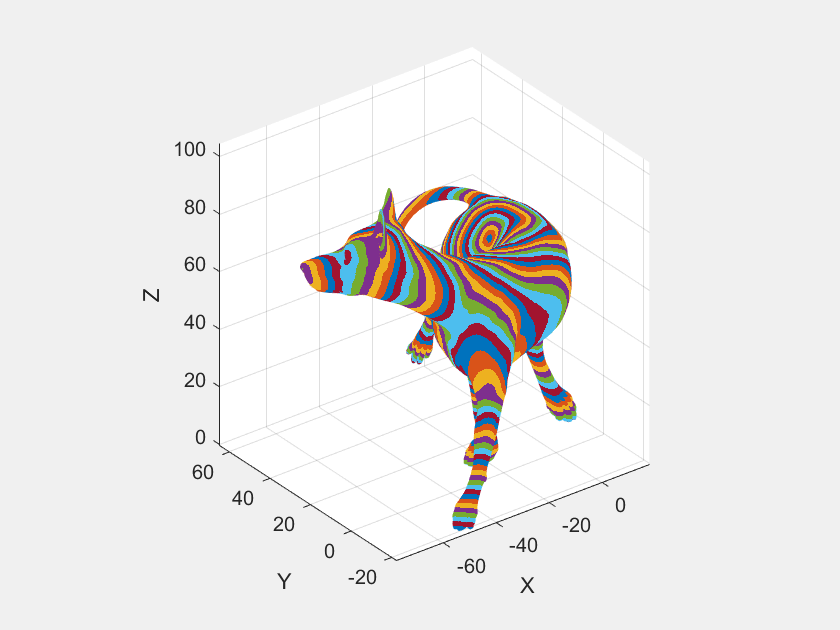

M = load_off('c:/users/rodola/workspace/data/tosca/dog10.off');
p = 1139;

q = 2.5;
dist = sum(abs(repmat(M.VERT(p,:),M.n,1) - M.VERT).^q,2).^(1/q);
figure, plot_scalar_map(M,dist), colormap(lines)